We gathered sitting, walking and running data in order to use for out fitness app. We will decide using a classification model whether the person using the app is sitting, walking or running by using some testing data we also gathered today. We will import the corresponding data we collected and train a model to predict which activity we are doing. We we use some testing data after the training in order to calculate the calories burned, steps made, distance travelled and the mood of the person. 

IMPORT SITTING DATA

sitData = load('sitting.mat');
% Rename SitAcceleration columns
sitData.Acceleration = renamevars(sitData.Acceleration, ...
    {'X', 'Y', 'Z'}, ...
    {'AccX', 'AccY', 'AccZ'});
% Rename SitAngularVelocity columns
sitData.AngularVelocity = renamevars(sitData.AngularVelocity, ...
    {'X', 'Y', 'Z'}, ...
    {'AngVelX', 'AngVelY', 'AngVelZ'});
% Rename SitOrientation columns
sitData.Orientation = renamevars(sitData.Orientation, ...
    {'X', 'Y', 'Z'}, ...
    {'OrientX', 'OrientY', 'OrientZ'});
sitData.Acceleration = timetable2table(sitData.Acceleration, "ConvertRowTimes", false);
sitData.AngularVelocity = timetable2table(sitData.AngularVelocity, "ConvertRowTimes", false);
sitData.Orientation = timetable2table(sitData.Orientation, "ConvertRowTimes", false);
sitTable = [sitData.Acceleration, sitData.AngularVelocity, sitData.Orientation];

IMPORT RUNNING DATA

runData = load('run.mat');
% Rename SitAcceleration columns
runData.Acceleration = renamevars(runData.Acceleration, ...
    {'X', 'Y', 'Z'}, ...
    {'AccX', 'AccY', 'AccZ'});
% Rename SitAngularVelocity columns
runData.AngularVelocity = renamevars(runData.AngularVelocity, ...
    {'X', 'Y', 'Z'}, ...
    {'AngVelX', 'AngVelY', 'AngVelZ'});
% Rename SitOrientation columns
runData.Orientation = renamevars(runData.Orientation, ...
    {'X', 'Y', 'Z'}, ...
    {'OrientX', 'OrientY', 'OrientZ'});
runData.Acceleration = timetable2table(runData.Acceleration, "ConvertRowTimes", false);
runData.AngularVelocity = timetable2table(runData.AngularVelocity, "ConvertRowTimes", false);
runData.Orientation = timetable2table(runData.Orientation, "ConvertRowTimes", false);
runData.Acceleration =runData.Acceleration(1:12500, :);
runData.AngularVelocity = runData.AngularVelocity(1:12500, :);
runData.Orientation = runData.Orientation(1:12500, :);
runTable = [runData.Acceleration, runData.AngularVelocity, runData.Orientation ];

IMPORT WALKING DATA

walkData = load('walk.mat');
% Rename SitAcceleration columns
walkData.Acceleration = renamevars(walkData.Acceleration, ...
    {'X', 'Y', 'Z'}, ...
    {'AccX', 'AccY', 'AccZ'});
% Rename SitAngularVelocity columns
walkData.AngularVelocity = renamevars(walkData.AngularVelocity, ...
    {'X', 'Y', 'Z'}, ...
    {'AngVelX', 'AngVelY', 'AngVelZ'});
% Rename SitOrientation columns
walkData.Orientation = renamevars(walkData.Orientation, ...
    {'X', 'Y', 'Z'}, ...
    {'OrientX', 'OrientY', 'OrientZ'});
walkData.Acceleration = timetable2table(walkData.Acceleration, "ConvertRowTimes", false);
walkData.AngularVelocity = timetable2table(walkData.AngularVelocity, "ConvertRowTimes", false);
walkData.Orientation = timetable2table(walkData.Orientation, "ConvertRowTimes", false);
walkData.Acceleration =walkData.Acceleration(1:14000, :);
walkData.AngularVelocity = walkData.AngularVelocity(1:14000, :);
walkData.Orientation = walkData.Orientation(1:14000, :);
walkTable = [walkData.Acceleration, walkData.AngularVelocity, walkData.Orientation ];

%%
sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(sitTable, 1), 1);
sitTable.Activity = sitLabel;
% Repeat for running data
runLabel = 'running';
runLabel = repmat(runLabel, size(runTable, 1), 1);
runTable.Activity = runLabel;
% Repeat for walking data
walkLabel = 'walking';
walkLabel = repmat(walkLabel, size(walkTable, 1), 1);
walkTable.Activity = walkLabel;
allData = [sitTable; runTable; walkTable;];

TRAIN THE MODEL USING CLASSIFICATION LEARNER GUI

For training, we will focus solely on acceleration and gyroscope measurements, as heading angles are more indicative of the direction we are moving rather than the activity we are performing. Accelerometers are particularly useful for identifying running patterns, as running typically involves more frequent acceleration and deceleration compared to walking, where the pace tends to be more steady. The result is the following with a validation accuracy of 99.0% and a testing accuracy of 98.9%.

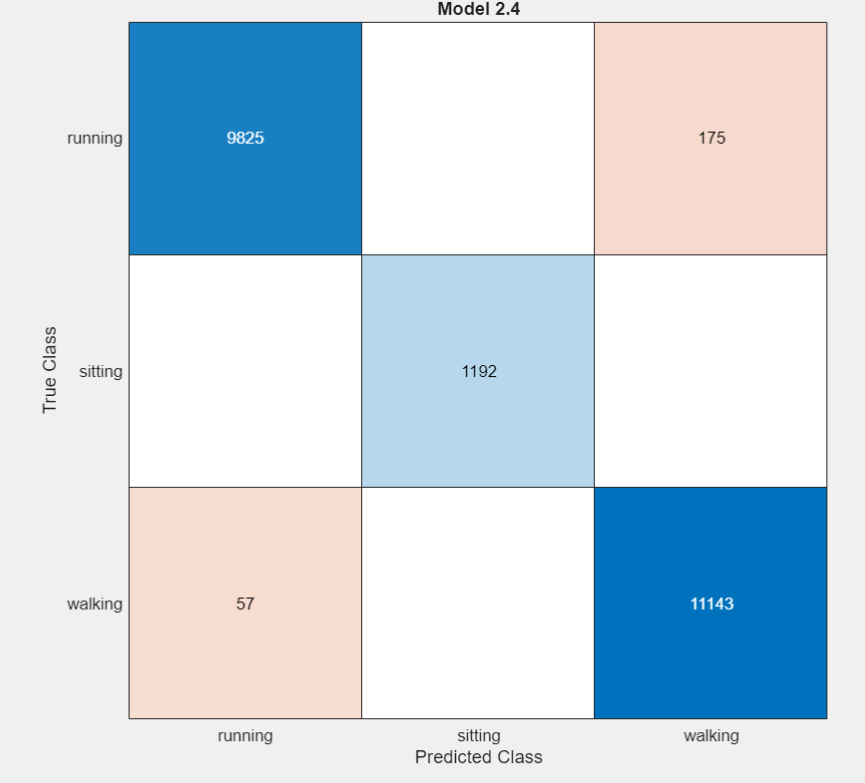

TESTING

For testing we will use some data which contain running and walking, for the first person.

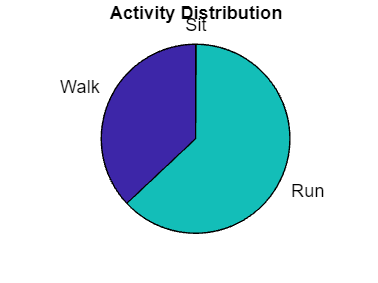

testData = load('walkingRunning.mat');
% Rename SitAcceleration columns
testData.Acceleration = renamevars(testData.Acceleration, ...
    {'X', 'Y', 'Z'}, ...
    {'AccX', 'AccY', 'AccZ'});
% Rename SitAngularVelocity columns
testData.AngularVelocity = renamevars(testData.AngularVelocity, ...
    {'X', 'Y', 'Z'}, ...
    {'AngVelX', 'AngVelY', 'AngVelZ'});
% Rename SitOrientation columns
testData.Orientation = renamevars(testData.Orientation, ...
    {'X', 'Y', 'Z'}, ...
    {'OrientX', 'OrientY', 'OrientZ'});

% we will assume that the duration of our activity is the duration in which
% we gather acceleration data
accelDatetime = testData.Acceleration.Timestamp;
accelTime=timeElapsed(accelDatetime);
duration = accelTime(end);

testData.Acceleration = timetable2table(testData.Acceleration(1:2417, :), "ConvertRowTimes", false);
testData.AngularVelocity = timetable2table(testData.AngularVelocity(1:2417, :), "ConvertRowTimes", false);
testData.Orientation = timetable2table(testData.Orientation(1:2417, :), "ConvertRowTimes", false);
testTable = [testData.Acceleration, testData.AngularVelocity];

loadedData = load('THEMODEL.mat');
THEMODEL = loadedData.THEMODEL;

yfit = THEMODEL.predictFcn(testTable);
cnt_walk = sum(yfit(:,1)=='w');
cnt_run = sum(yfit(:, 1)=='r');
cnt_sit = sum(yfit(:, 1)=='s');
total = size(yfit, 1);

walk_perc = cnt_walk / total;
run_perc = cnt_run / total;
sit_perc = cnt_sit / total;

activity_perc = [walk_perc, run_perc, sit_perc];
labels = {'Walk', 'Run', 'Sit'};

figure; 
pie(activity_perc, labels);
title('Activity Distribution'); 

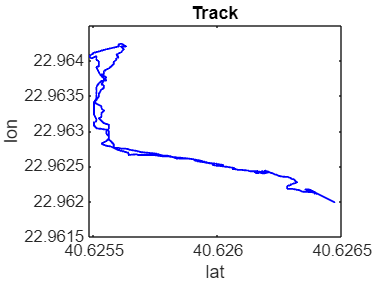


% if running predictions exceed walking predictions we will assume the
% person is running, otherwise we will assume the person is walking
if cnt_run > cnt_walk
    yfit_labels_walk = false;
    yfit_labels_run = true;
    activity = 'running';
elseif cnt_run < cnt_walk
    yfit_labels_walk = true;
    yfit_labels_run = false;
    activity = 'walking'
end

% we calculate the total steps and distance travelled
[steps, totaldis] = total_dist_and_steps_calc(yfit_labels_run, yfit_labels_walk, 'walkingRunning.mat');


fprintf("Total steps: %f", steps)

Total steps: 587.257664

fprintf("Total distance travelled: %f km", totaldis)

Total distance travelled: 0.333669 km


% we will calculate the calories burned assuming the person weighs 70 kg
cal = calories_burned(70, duration, activity);

fprintf("Calories burned: %f", cal)

Calories burned: 2655.602775


% caluclate mood
[cnt_stress, cnt_calm] = definemood('walkingRunning.mat');

if cnt_stress > cnt_calm
    fprintf("You are stressed :(");
else
    fprintf("You are calm :)");
end

You are stressed :(